clear
clc


% 1 Run model
open('Longitudinal_U.slx')
out = sim('Longitudinal_U.slx');

% 2 Extract time and signal data
t = out.h.Time;

h = out.h.Data .* 10;

u = out.u.Data;
w = out.uref.Data .* 10;
q = out.uref.Data;
theta = out.uref.Data;

theta_0 = out.theta_0.Data;
theta_1s = out.theta_1s.Data;
delta_E = out.delta_E.Data;

href = out.href.Data .* 10;
uref = out.uref.Data;


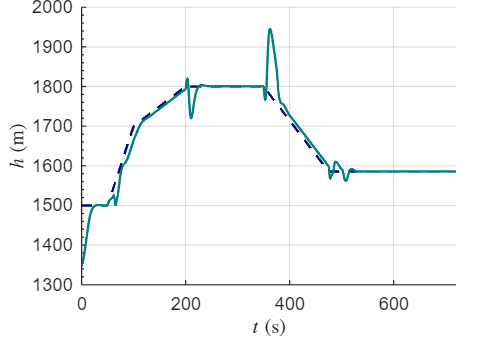

% 3 Compute step response characteristics

figure(1)

[ha, pos] = tight_subplot(1,1, ...   % Nh, Nw
                          [0.08 0.08], ...
                          [0.21 0.02], ...    % marg_h [bottom top]
                          [0.17 0.05]);       % marg_w [left  right]

ax = ha(1);            % handle to the only axes
axes(ax);              % activate it

plot(t, href, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5);
hold on
plot(t, h, 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5);
hold off

set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

xlim([0 720]);
ylim([1300 2000]);

xlabel('$t \; (\mathrm{s})$', 'Interpreter', 'latex');
ylabel('$h \; (\mathrm{m})$', 'Interpreter', 'latex');
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set figure size
set(gcf, 'Position', [0 0 400 300]);

sqrt(mean((href - h).^2))

ans = 53.2345

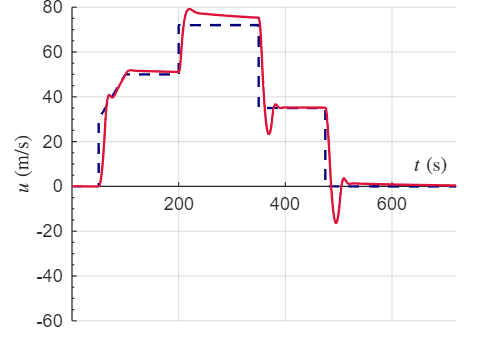


figure(2)

[ha, pos] = tight_subplot(1,1, ...   % Nh, Nw
                          [0.08 0.08], ...
                          [0.11 0.02], ...    % marg_h [bottom top]
                          [0.15 0.05]);       % marg_w [left  right]

ax = ha(1);            % handle to the only axes
axes(ax);              % activate it

plot(t, uref, '--', 'Color', [0/255 0/255 128/255], 'LineWidth', 1.5);
hold on
plot(t, u, 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5);
hold off

set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

xlim([0 720]);
ylim([-60 80]);

xlabel('$t \; (\mathrm{s})$', 'Interpreter', 'latex');
ylabel('$u \; (\mathrm{m/s})$', 'Interpreter', 'latex');

grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set figure size
set(gcf, 'Position', [0 0 400 300]);

sqrt(mean((uref - u).^2))

ans = 17.0091